% Heat transfer coefficients
h_i = 15; % W/m^2-K
h_o = 25; % W/m^2-K
h_window = 0.7; % W/m^2-K ==== equivalent based on inner pane to outerpane 

% Conductivities
k_fiberglass = 0.04; % W/m-K

% House dimensions
depth = 5; % m
length_tile = 5.1; % m
height_window = 3; % m
control_length = 0.9; % m
height_fiberglass = 3; % m
length_fiberglass = 5.1; % m
thickness_fiberglass = 0.001; % m
thickness_tile = 0.1;

% Areas
area_tile = depth * length_tile; % m^2
area_window = depth * height_window; % m^2
area_under_house = depth * (length_tile + 2*thickness_fiberglass); % m^2
area_fiberglass_inside = 2*height_fiberglass*length_fiberglass ...
                         + height_fiberglass * depth ...
                         + length_fiberglass * depth; % m^2
area_fiberglass_outside = 2*(height_fiberglass + 2 * thickness_fiberglass)*(length_fiberglass + 2 * thickness_fiberglass)...
                         + (height_fiberglass + 2 * thickness_fiberglass) * (depth + 2 * thickness_fiberglass) ...
                         + (length_fiberglass + 2 * thickness_fiberglass) * (depth + 2 * thickness_fiberglass); % m^2

% Specific heats
rho_tile = 3000; % kg/m^3
c_tile = 800; % J/kg-K
rho_air = 1.2; % kg/m^3 ==== from QEA book 3.2
c_air = 1000; % J/kg-K ==== from QEA book 3.2

mass_tile = depth * length_tile * thickness_tile * rho_tile;
mass_air = depth * height_fiberglass * length_fiberglass * rho_air;

C_tile = mass_tile * c_tile;
C_air = mass_air * c_air;

% Resistances
R_floor_to_air = (h_i * area_tile)^-1; % K/W
R_floor_to_outside = (thickness_fiberglass / k_fiberglass / area_tile) ...
                     + (h_o * area_under_house); % K/W
R_air_to_outside = (h_i * area_fiberglass_inside)^-1 ...
                    + (thickness_fiberglass / k_fiberglass / area_fiberglass_inside) ...
                    + (h_o * area_fiberglass_outside)^-1; % K/W
R_air_w_outside = (h_i * area_window)^-1 ...
                    + (h_window * area_window)^-1 ...
                    + (h_o * area_window)^-1; % K/W

% FUNCTIONS                
% The given solar flux function
f_solar_flux = @(t) -361 * cos(pi * t/(12 * 3600)) + 224 * cos(pi * t/(6 * 3600)) + 210;

% Given outside air temperature
f_outside_air = @(t) -3 + 6*sin( (2*pi*t)/(24*3600) + 3*pi/4 );

% Insolation length function derived with geometry
f_radiation_length = @(angle) min(cotd(angle) .* (height_window - control_length*tand(angle)), length_tile);

% Wrap sun angle function to just take seconds
% Converts seconds to day-of-year and hour-of-day
f_sun_angle_seconds = @(t) 90 - sunAngle(t / 3600 / 24, mod(t / 3600, 24));

% Solar flux in in seconds since 1/1
f_Q_in = @(t) f_solar_flux(t) .* f_radiation_length(f_sun_angle_seconds(t)) * depth;
f_Q_in_const_angle = @(t) f_solar_flux(t) .* f_radiation_length(25) * depth; % Assume constant solar angle

% Y: Vector of states = [T_floor; T_air]
% So, y(1) = T_floor, y(2) = T_air
f_rates = @(t, y) [ ...
    % dT_floor/dt
    (f_Q_in_const_angle(t) - (y(1) - y(2))/R_floor_to_air - (y(1) - f_outside_air(t))/R_floor_to_outside) / C_tile; ...
    
    % dT_air/dt
    ((y(1) - y(2))/R_floor_to_air - (y(2) - f_outside_air(t))/R_air_w_outside - (y(2) - f_outside_air(t))/R_air_to_outside) / C_air...
];

days = 20;
day_0 = 0;
t_0 = 0;
tspan = linspace(t_0, t_0 + days*24*3600, days*24*3600);

figure()
yyaxis left

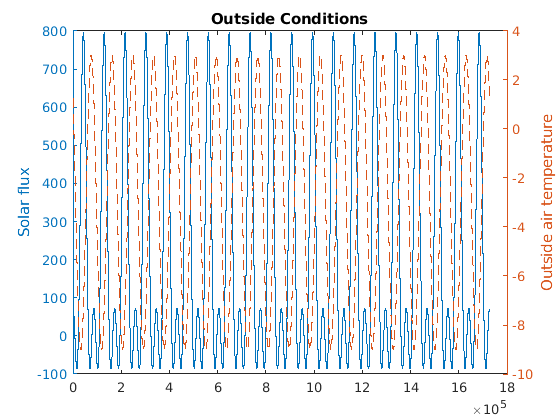

plot(tspan, f_solar_flux(tspan));
ylabel("Solar flux")

yyaxis right
plot(tspan, f_outside_air(tspan), '--');
ylabel("Outside air temperature")
title("Outside Conditions")

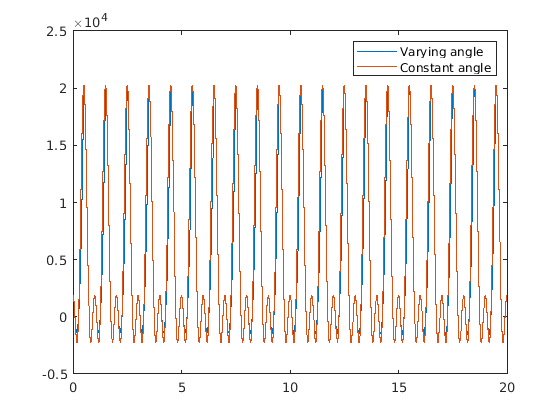

figure()
plot(tspan/3600/24, [f_Q_in(tspan);f_Q_in_const_angle(tspan)])
legend("Varying angle", "Constant angle")

% Y: Vector of states = [T_floor; T_air]
% So, y(1) = T_floor, y(2) = T_air
f_rates = @(t, y) [ ...
    % dT_floor/dt
    (f_Q_in_const_angle(t) - (y(1) - y(2))/R_floor_to_air - (y(1) - f_outside_air(t))/R_floor_to_outside) / C_tile; ...
    
    % dT_air/dt
    ((y(1) - y(2))/R_floor_to_air - (y(2) - f_outside_air(t))/R_air_w_outside - (y(2) - f_outside_air(t))/R_air_to_outside) / C_air...
];

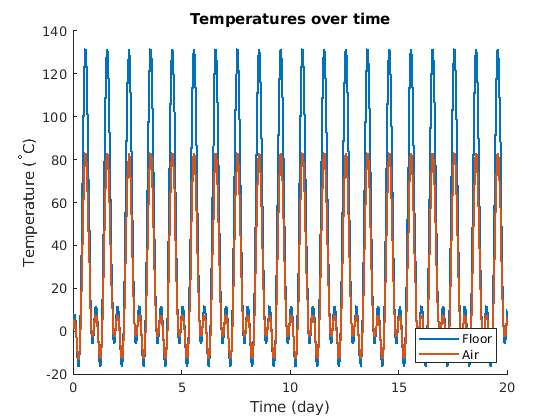

y_0 = zeros([2, 1]) + f_outside_air(tspan(1));
[t_out, Y_out] = ode_solver(0.01,0.01,tspan);
figure();
hold on
plot(t_out/(3600 * 24), Y_out, 'linewidth', 1.5)
title("Temperatures over time")
xlabel("Time (day)")
ylabel("Temperature (^\circC)")
legend("Floor", "Air", 'location', 'southeast')